Opgaver

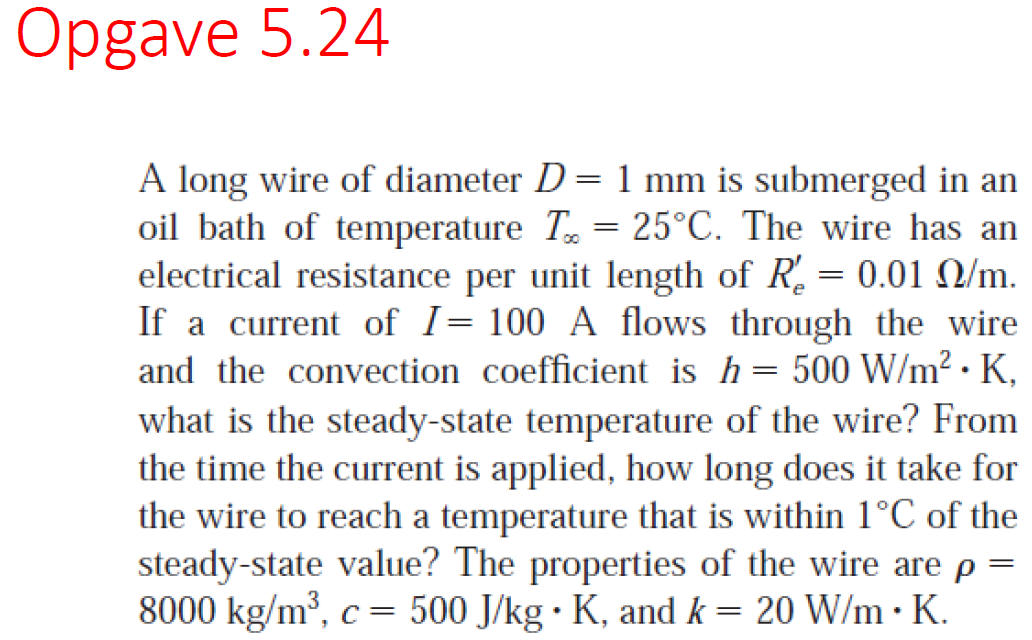


$$L_c \equiv  V/A_s$$


clear all
clf
T_inf = 25 + 273.15; % K
D = 1e-3; %m
I = 100; %A
R_e = 0.01; %ohm/m
h = 500; % W/(m^2 * K)
rho = 8000; % kg/m^3
c_p = 500; %J/(kg * K)
k = 20; % W/(m * K)
r = D/2;
syms L T_t

**check biots number**

Hvis biots tal er lavt Bi<<1 kan der antages ens artet varmefordeling (steady state)

Lc = r;
Bi = h * Lc / k % < 0.1

Bi =                     0.0125


Vi kan benytte Lumped Capacitance Method

A = 2 * pi * r * L

$$A = \frac{\pi \,L}{1000}$$

V = L * pi * r^2

$$V = \frac{4722366482869645\,\pi \,L}{18889465931478580854784}$$

P = R_e * I^2

P =    100


q_eq = P == h * A/L * (T_t - T_inf)

$$q\_eq = 100=\frac{\pi \,\left(T_{t}-\frac{5963}{20}\right)}{2}$$


T_t = vpa(solve(q_eq, T_t), 8);
T_t_c = double(T_t - 273.15)

T_t_c =           88.6619772367581


T_t = double(T_t)

T_t =           361.811977236758


fra exsempel 1.4

% tau_0 = rho * V/L *c_p / (h * A) % sekunder
% % vpa(tau_0, 10)
T_i = T_inf;
% t = rho * Vc
syms t
t_eq = (T_t-T_inf-1 - I^2*R_e/(pi * D*h)) / (T_i-T_inf - I^2*R_e/(pi * D*h)) == exp(- 4*h / (rho*c_p*D) * t);
t_1 = vpa(solve(t_eq, t),6)

$$t\_1 = 8.30717$$

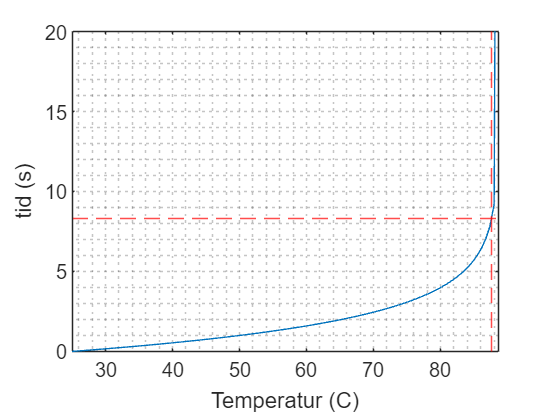


Ts = linspace(T_inf,T_t,100);
syms t
ts_eq = (Ts-T_inf - I^2*R_e/(pi * D*h)) / (T_i-T_inf - I^2*R_e/(pi * D*h)) == exp(- 4*h / (rho*c_p*D) * t);
for i = 1:length(Ts)
    ts_now = solve(ts_eq(i), t);
    ts(i) = double(ts_now);
end
% double(vpa(solve(ts_eq, t),5))

plot(Ts-273.15, ts)
xline(T_t - 1 - 273.15,'--r')
yline(double(t_1),'--r')
ylabel('tid (s)')
xlim([T_inf,T_t]-273.15)
ylim([0,20])
xlabel('Temperatur (C)')
grid('minor')

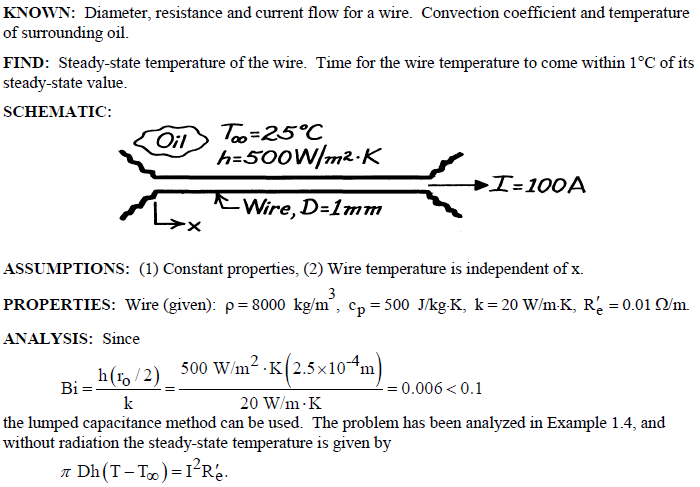

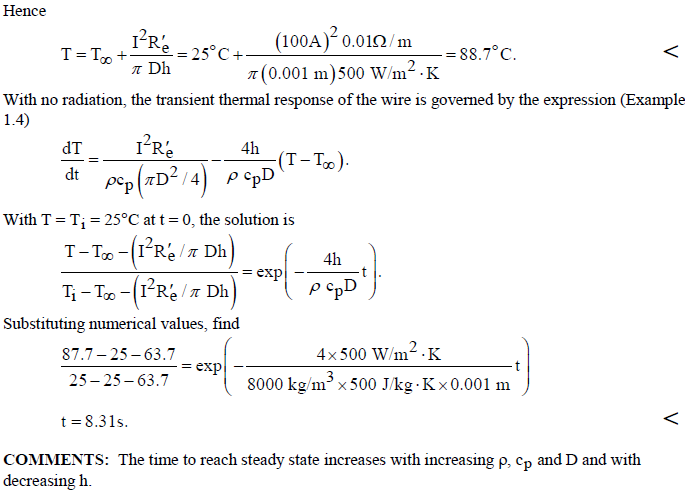

**Opgave 5.37**

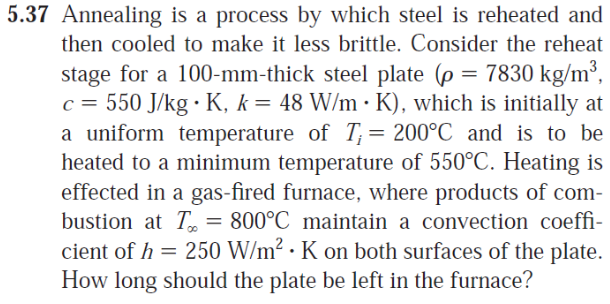

clear all 
clf
thick = 0.1; % m tykkelse af stål plade
rho = 7830; % kg/m^3 %densistet af stål
c = 550; % J/(kg * K) varme capacitet af stål
k = 48; % W/(m * K)
Ti = 200 + 273.15; % K
Tmin = 550 + 273.15; % K % minmum anealing temp
Tinf = 800 + 273.15; % K % ovn temperatur
h = 250; % W/(m^2 * K) % convections coefficent

Lc = thick/2;
Bi = h * Lc / k % < 0.1

Bi =          0.260416666666667


Vi kan benytte Lumped Capacitance Method

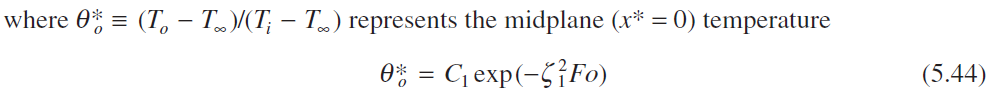

[zeta1_interp, C1_interp] = interpolateBiValues(Bi)

zeta1_interp = struct with fields:
           PlaneWall: 0.50156285060082
    InfiniteCylinder: 0.80830322909209
              Sphere: 0.934313269401529


C1_interp = struct with fields:
           PlaneWall: 1.04260380973214
    InfiniteCylinder: 1.06049194830341
              Sphere: 1.11607458036607


zeta1 = zeta1_interp.PlaneWall

zeta1 =           0.50156285060082


C1 = C1_interp.PlaneWall

C1 =           1.04260380973214



 
% t_eq

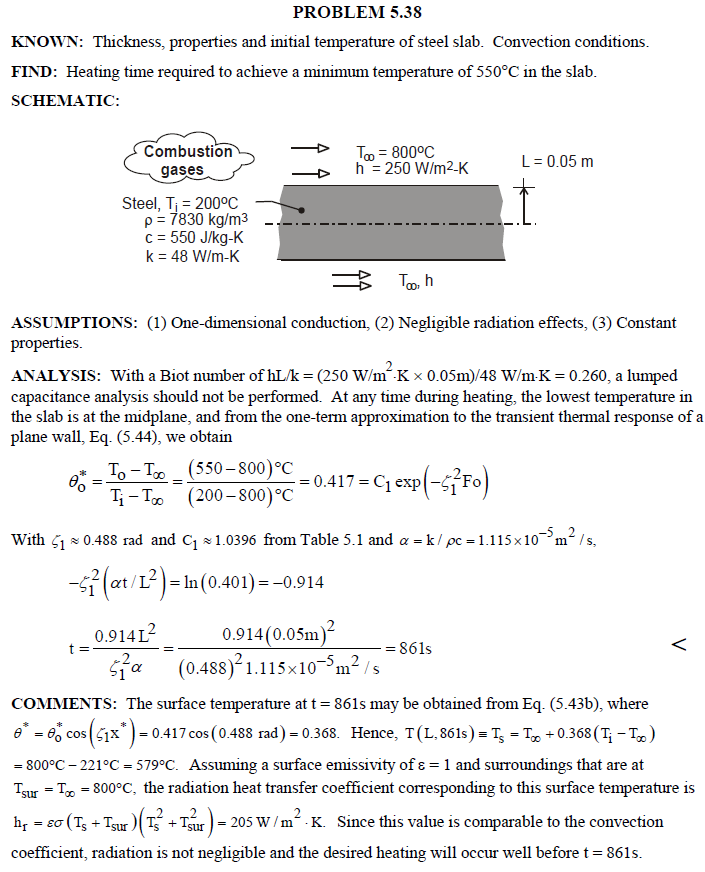

**Opgave 5.67**

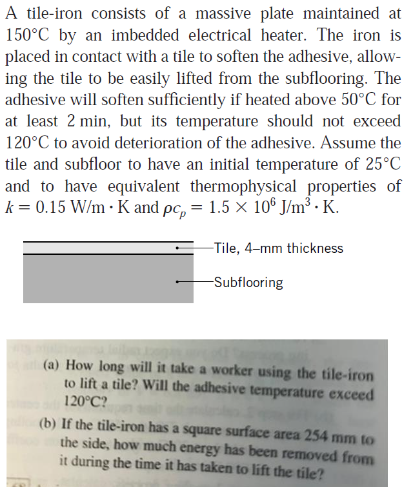

Figurer

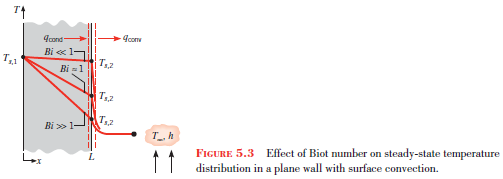

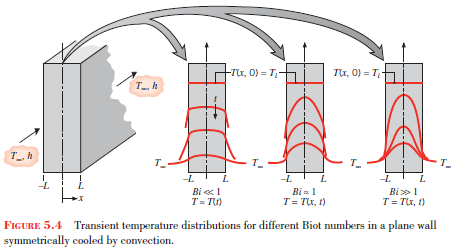

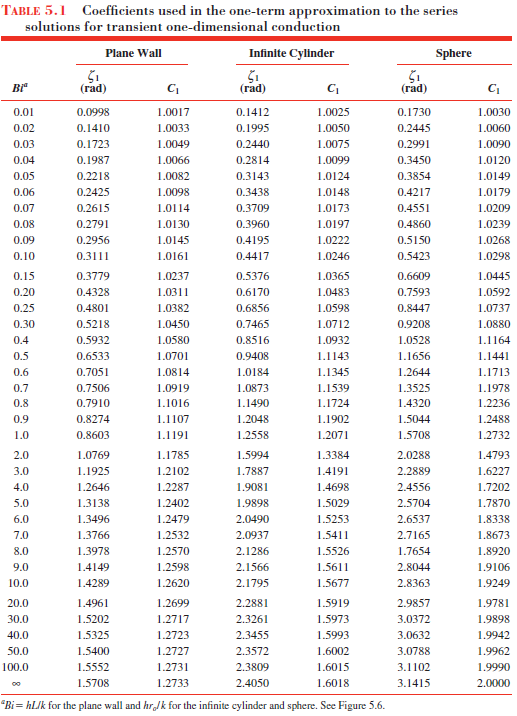

% Bi values
Bis = [0.01, 0.02, 0.03, 0.04, 0.05, 0.06, 0.07, 0.08, 0.09, 0.1, 0.2, 0.3, ...
      0.4, 0.5, 0.6, 0.7, 0.8, 0.9, 1.0, 1.5, 2.0, 3.0, 4.0, 5.0, 6.0, 7.0, ...
      8.0, 9.0, 10.0, 20.0, 30.0, 40.0, 50.0];

% Plane Wall
zeta1_plane_wall = [0.0998, 0.1410, 0.1723, 0.1944, 0.2118, 0.2261, 0.2385, ...
                    0.2490, 0.2580, 0.2663, 0.4328, 0.5397, 0.6224, 0.6900, ...
                    0.7470, 0.7962, 0.8396, 0.8786, 0.9142, 1.1584, 1.3092, ...
                    1.4474, 1.5532, 1.6345, 1.6986, 1.7508, 1.7943, 1.8318, ...
                    1.8651, 1.4961, 1.5325, 1.5508, 1.5508];
C1_plane_wall = [1.0017, 1.0033, 1.0049, 1.0062, 1.0073, 1.0082, 1.0090, ...
                 1.0097, 1.0105, 1.0111, 1.0311, 1.0494, 1.0632, 1.0744, ...
                 1.0838, 1.0917, 1.0984, 1.1041, 1.1091, 1.1787, 1.2226, ...
                 1.2537, 1.2734, 1.2859, 1.2939, 1.2997, 1.3041, 1.3075, ...
                 1.3102, 1.2699, 1.2723, 1.2731, 1.2731];

% Infinite Cylinder
zeta1_inf_cyl = [0.1412, 0.1990, 0.2440, 0.2815, 0.3134, 0.3413, 0.3661, ...
                 0.3885, 0.4095, 0.4297, 0.6971, 0.8703, 1.0058, 1.1173, ...
                 1.2118, 1.2945, 1.3680, 1.4344, 1.4950, 1.9348, 2.2303, ...
                 2.4790, 2.6875, 2.8666, 3.0245, 3.1670, 3.2973, 3.4171, ...
                 3.5285, 3.8940, 4.0570, 4.1359, 4.1359];
C1_inf_cyl = [1.0025, 1.0075, 1.0115, 1.0148, 1.0174, 1.0196, 1.0215, ...
              1.0231, 1.0245, 1.0257, 1.0483, 1.0677, 1.0830, 1.0950, ...
              1.1043, 1.1119, 1.1182, 1.1235, 1.1280, 1.4098, 1.5698, ...
              1.6960, 1.7974, 1.8793, 1.9472, 2.0040, 2.0510, 2.0914, ...
              2.1266, 2.5096, 2.6254, 2.6825, 2.6825];

% Sphere
zeta1_sphere = [0.1730, 0.2491, 0.2991, 0.3388, 0.3727, 0.4028, 0.4297, ...
                0.4541, 0.4764, 0.4969, 0.8053, 1.0057, 1.1584, 1.2825, ...
                1.3868, 1.4773, 1.5570, 1.6286, 1.6937, 2.2230, 2.5753, ...
                2.8318, 3.0315, 3.1952, 3.3347, 3.4571, 3.5662, 3.6651, ...
                3.7559, 3.9515, 4.0575, 4.1118, 4.1118];
C1_sphere = [1.0030, 1.0073, 1.0114, 1.0146, 1.0171, 1.0192, 1.0210, ...
             1.0226, 1.0240, 1.0252, 1.0972, 1.1256, 1.1473, 1.1632, ...
             1.1757, 1.1857, 1.1942, 1.2015, 1.2074, 1.4732, 1.6227, ...
             1.7496, 1.8582, 1.9527, 2.0357, 2.1090, 2.1744, 2.2331, ...
             2.2878, 2.7040, 2.8479, 2.9242, 2.9242];

help interp1

 interp1 1-D interpolation (table lookup)
 
    Vq = interp1(X,V,Xq) interpolates to find Vq, the values of the
    underlying function V=F(X) at the query points Xq. 
 
    X must be a vector. The length of X is equal to N.
    If V is a vector, V must have length N, and Vq is the same size as Xq.
    If V is an array of size [N,D1,D2,...,Dk], then the interpolation is
    performed for each D1-by-D2-by-...-Dk value in V(i,:,:,...,:). If Xq
    is a vector of length M, then Vq has size [M,D1,D2,...,Dk]. If Xq is 
    an array of size [M1,M2,...,Mj], then Vq is of size
    [M1,M2,...,Mj,D1,D2,...,Dk].
 
    Vq = interp1(V,Xq) assumes X = 1:N, where N is LENGTH(V)
    for vector V or SIZE(V,1) for array V.
 
    Interpolation is the same operation as "table lookup".  Described in
    "table lookup" terms, the "table" is [X,V] and interp1 "looks-up"
    the elements of Xq in X, and, based upon their location, returns
   

zeta = interp1(Bis, zeta1_plane_wall,Bi, 'linear')

zeta =          0.497385416666667


C1 = interp1(Bis, C1_plane_wall,Bi, 'linear')

C1 =                 1.04215625
